daq.getDevices()

ans = ni: National Instruments USB-6001 (Device ID: 'Dev1')
   Analog input subsystem supports:
      -10 to +10 Volts range
      Rates from 0.1 to 20000.0 scans/sec
      8 channels ('ai0' - 'ai7')
      'Voltage' measurement type
   
   Analog output subsystem supports:
      -10 to +10 Volts range
      Rates from 0.1 to 5000.0 scans/sec
      2 channels ('ao0','ao1')
      'Voltage' measurement type
   
   Digital subsystem supports:
      13 channels ('port0/line0' - 'port2/line0')
      'InputOnly','OutputOnly','Bidirectional' measurement types
   
   Counter input subsystem supports:
      1 channel ('ctr0')
      'EdgeCount' measurement type
   

Properties, Methods, Events



s=daq.createSession('ni')

s = Data acquisition session using National Instruments hardware:
   Will run for 1 second (1000 scans) at 1000 scans/second.
   No channels have been added.
   
Properties, Methods, Events


ch=addAnalogInputChannel(s,'Dev1','ai0','Voltage')

ch = Data acquisition analog input voltage channel 'ai0' on device 'Dev1':

       Coupling: DC
 TerminalConfig: Differential
          Range: -10 to +10 Volts
           Name: ''
             ID: 'ai0'
         Device: [1x1 daq.ni.DeviceInfo]
MeasurementType: 'Voltage'


Properties, Methods, Events


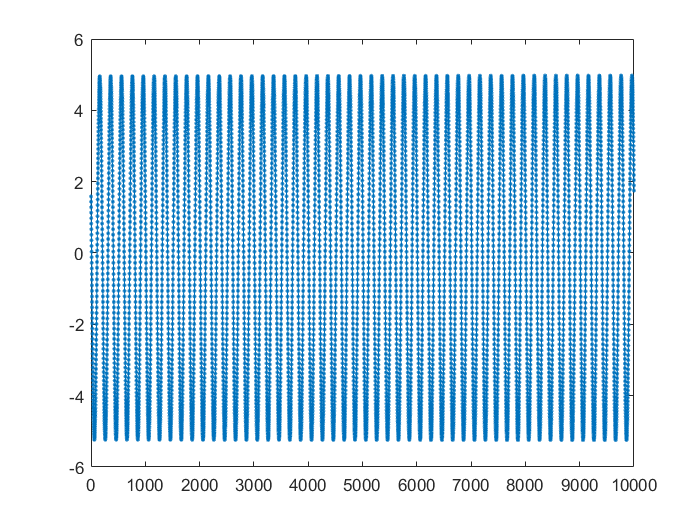

s.Rate=10000;
data=s.startForeground();
figure;
plot(data,'.-')

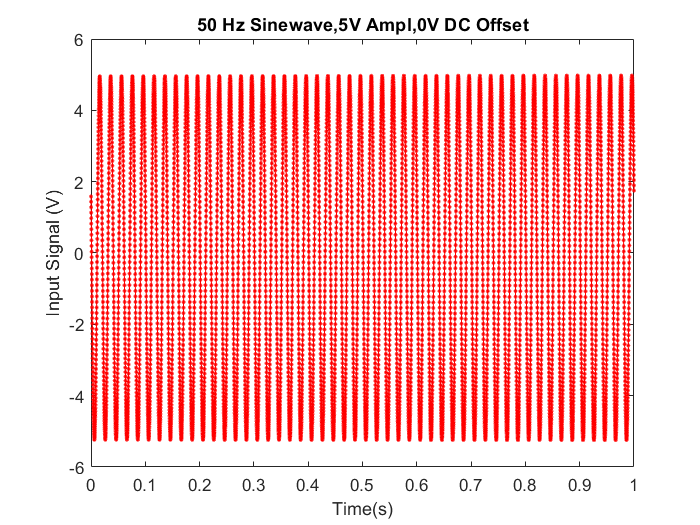

dt=1/s.Rate;
t_end=double(s.NumberOfScans)*dt;
time=[dt:dt:t_end];
figure;
plot(time,data,'r.-');
xlabel('Time(s)');
ylabel('Input Signal (V)');
title('50 Hz Sinewave,5V Ampl,0V DC Offset')